# **Create a massspectrum and define ranges**

This Livescript will guid you through the first steps of the reconstruction of an Atom-Probe-Dataset with this toolbox.

First of all you have to load some basics as the clolorScheme which provides color for all elements of the periodic table. In isotopeTable_naturalAbundances all isotopes of the elements there weight, abundance and atomDensity are given. After this you can load your *.pos file. An window will pop-up and you can choose your file. If you have an *.epos file be aware you change your selection window on *.epos. 

load isotopeTable_naturalAbundances.mat
load colorScheme.mat
pos = posToTable;

file R56_01769-v01.pos loaded


When the pos file is loaded you can plot your massspectrum. You can change the step width and the plotting mode as seen in the code. A mode is 'count' which only shows the number of counts above the mass-to-charge ratio the other is 'normalized' which shows number of the counts per Dalton over total counts.

bin = 0.061% Width of the steps in which the plot is performed

bin = 0.0610

mode = 'normalised' % Specifies the way the counts are applied

mode = 'normalised'

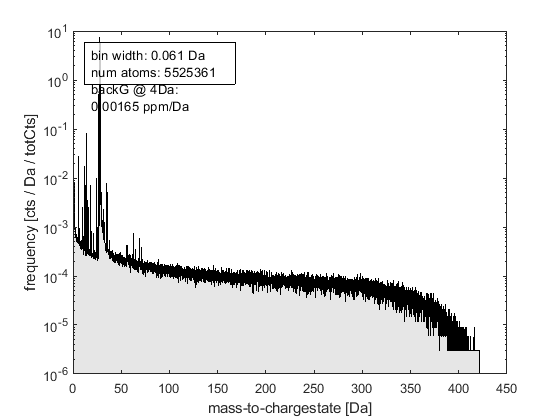

Error using matlab.graphics.interaction.webmodes.toggleMode
Unknown action character vector.

Error in matlab.graphics.interaction.webmodes.modeHelper

Error in matlab.graphics.interaction.webmodes.modeFunctionHelper

Error in matlab.graphics.interaction.webmodes.panWeb

Error in pan (line 206)
            matlab.graphics.interaction.webmodes.panWeb(arg1, []);

Error in massSpecPlot (

spec = massSpecPlot(pos,bin,mode); % Plots your massspectrum

After you plotted your massspectrum you can now range your dataset in two ways.

## Adding ions with knownledge of occurring ions

To add an know ion to your massspectrum you only need to use the ionAdd function. Therefore you first parse the massspectrum in which the range should be plotted. After this you enter the name of your ion, the chargestate of the ion which can be an vector. You also have to enter the margin within which two peaks will be summed up, the minimal abundance, the height of the most abundant isotope, which can be choosen as 'selection' and 'most abundat', and the maximal seperation of two peaks.

%please give the following in your comandline: spec = massSpecPlot(pos,bin,mode);
ion = 'Fe' % chemical symbol of the ion that will be added
chargeState = 2 % charge state of the ion, vector of charge states
sumMargin = 0 % specifies a margin within which two peaks will be summed up
minAbundance = 0 % is the minimal abundance
maxHeight = 'most abundant' % is the height of the most abundant isotope
maxSeparation = 0.1 % the maximum of the mass spectrum within this range will be used for scaling

ionAdd(spec,ion,chargeState,isotopeTable,colorScheme,sumMargin,minAbundance,maxHeight,maxSeparation) % ionAdd creates a stem plot in the mass spectrum (spec) for the parsed ion and its corresponding charge state

 

For deleting ions just click on them with the mous in edit plot and press delete.

## Adding ions without knowledge of occurring ions

To add an unknown ion to your massspectrum ionFind will be the right choice. To execute this function you first have to create an ionTable which contains all possible ions. Therefore you have to dicide which ions should be build you can choose 'all' or an list of wanted ions. You also have to set the maximal compelxity of the ions and the complex formers. A list of the standard complex formers is in the discription of the fuction, any other ions can be parsed also. The abundanceThreshold defines an threshold for used isotopes to build the list.

elements = 'all' % can be a list of atomic numbers, symbols or 'all'

elements = 'all'

chargeStates = [1 2 3] % list of chargeStates

chargeStates =      1     2     3


maxComplexity = 2 %  maximal complexity of the created ions

maxComplexity = 2

complexFormers = 'std' %  if complexformers = 'std' complexformers = H, H2, H3, C, C2, C3, N, O, O2. If complexFormers = 'and C P ....' it takes the elements in elements and adds the additional specified elements

complexFormers = 'std'

abundanceThreshold = 0.001 % sets an threshold for used isotopes to build the list

abundanceThreshold = 1.0000e-03

ionTable = ionTableCreate(elements,chargeStates,maxComplexity,complexFormers,abundanceThreshold,isotopeTable);

Dot indexing is not supported for variables of this type.

Error in ionTableCreate (line 38)
    elements = unique(isotopeTable.element);

After creating the ionTable adding ranges can be done with the ionFind function. Therefor only execute the function an then click on the peak you want to know. An popup-window will appear that indicates possible ions that matches to the selected peak. you can then choose the most suitable entry from this list.

searchRange = 0% range in which suggested ions resemble the peak
ionFind(spec,ionTable,isotopeTable,colorScheme,searchRange);
 

## Ranging of the added ions

Now we can start adding ranges to the ions we defined in our massspectrum. there for we use rangeAdd which uses the massspectrum and the colorScheme to add an range. it also reports total or partially overlaps. you have to run the function for every range you wnat to define.

rangeAdd(spec,colorScheme); % you can manually range your massspectrum
 